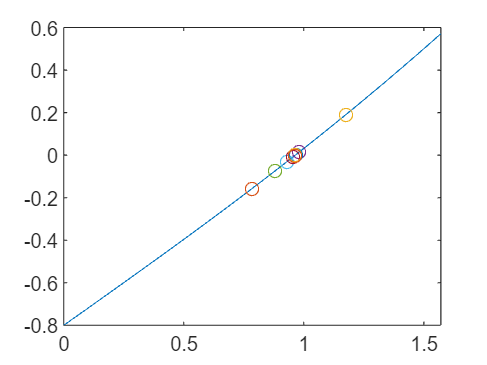

e = 9.5874e-05

i = 15

p = 0.9643

a = 0;
b = pi/2;
z = linspace(a,b,100);
y1 = myfun(z);

plot(z,y1);hold on

TOL = 10.^-4;
NMax = 300 ;
for i = 1:NMax
p = (a+b)/2;
e = abs(b-a);
FP = myfun(p);
FA = myfun(a);
if FA*FP >0 
    a = p;
else
    b = p;
end


plot(p, myfun(p), 'Marker','o')
if e < TOL
    e
    i
    p
    break;
    
end
if FP == 0
    break;
end
if i == NMax +1 
    fprintf('Max Iterations Reached No Solution Found') 
end
 

end

function y1 = myfun(x)
    y1 = x - 0.8 - 0.2*sin(x) ;
end